clear; clc;

%% Definición de símbolos
syms t s realPos

% Definición de matrices y parámetros
A = [0 1; -1 -1];
B = [1; 0];
C = [1 0];

% Valores propios de A
eigenvalues = eig(A);
disp('Valores propios de A:');

Valores propios de A:


disp(eigenvalues);

  -0.5000 + 0.8660i
  -0.5000 - 0.8660i




% Polinomio característico
ps = det(s*eye(2) - A);
disp('Polinomio característico:');

Polinomio característico:


disp(ps);

$$s^{2}+s+1$$


% Sistema en espacio de estado y función de transferencia
sistema = ss(A, B, C, 0);
FT = tf(sistema);
disp('Función de transferencia:');

Función de transferencia:


disp(FT);

  tf with properties:

       Numerator: {[0 1 1]}
     Denominator: {[1 1 1.0000]}
        Variable: 's'
         IODelay: 0
      InputDelay: 0
     OutputDelay: 0
              Ts: 0
        TimeUnit: 'seconds'
       InputName: {''}
       InputUnit: {''}
      InputGroup: [1×1 struct]
      OutputName: {''}
      OutputUnit: {''}
     OutputGroup: [1×1 struct]
           Notes: [0×1 string]
        UserData: []
            Name: ''
    SamplingGrid: [1×1 struct]




% Transformada de Laplace de la entrada
Us = laplace(sin(t), t, s);

% Respuesta homogénea
x0 = [0; 0];
xh_s = ilaplace(inv(s*eye(2) - A) * x0);

% Respuesta particular
xp_s = ilaplace(inv(s*eye(2) - A) * B * Us);

% Respuesta total x(t) y y(t)
x_s = xh_s + xp_s;
y_s = C * x_s;

disp('Respuesta x(t):');

Respuesta x(t):


disp(x_s);

$$\left(\begin{array}{c} \sin\left(t\right)-\cos\left(t\right)+{\mathrm{e}}^{-\frac{t}{2}}\,\left(\cos\left(\frac{\sqrt{3}\,t}{2}\right)-\frac{\sqrt{3}\,\sin\left(\frac{\sqrt{3}\,t}{2}\right)}{3}\right)\\ \cos\left(t\right)-{\mathrm{e}}^{-\frac{t}{2}}\,\left(\cos\left(\frac{\sqrt{3}\,t}{2}\right)+\frac{\sqrt{3}\,\sin\left(\frac{\sqrt{3}\,t}{2}\right)}{3}\right) \end{array}\right)$$

disp('Respuesta y(t):');

Respuesta y(t):


disp(y_s);

$$\sin\left(t\right)-\cos\left(t\right)+{\mathrm{e}}^{-\frac{t}{2}}\,\left(\cos\left(\frac{\sqrt{3}\,t}{2}\right)-\frac{\sqrt{3}\,\sin\left(\frac{\sqrt{3}\,t}{2}\right)}{3}\right)$$

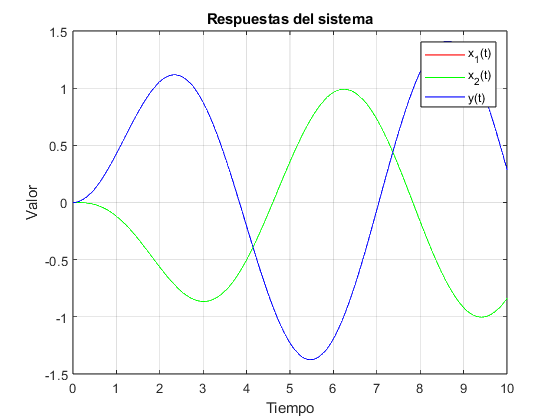


% Convertir a funciones anónimas para evaluación rápida
x1_func = matlabFunction(x_s(1));
x2_func = matlabFunction(x_s(2));
y_func = matlabFunction(y_s);

% Gráfica de las respuestas
time_vec = 0:0.01:10; % Vector de tiempo, ajustar según necesidad
x1_values = arrayfun(x1_func, time_vec);
x2_values = arrayfun(x2_func, time_vec);
y_values = arrayfun(y_func, time_vec);

figure;
plot(time_vec, x1_values, 'r', 'DisplayName', 'x_1(t)');
hold on;
plot(time_vec, x2_values, 'g', 'DisplayName', 'x_2(t)');
plot(time_vec, y_values, 'b', 'DisplayName', 'y(t)');
xlabel('Tiempo');
ylabel('Valor');
title('Respuestas del sistema');
legend('show');
grid on;
hold off;


% Guardar funciones en archivos .m
matlabFunction(x_s(1), 'File', 'x1_func', 'Vars', {t});
matlabFunction(x_s(2), 'File', 'x2_func', 'Vars', {t});
matlabFunction(y_s, 'File', 'y_func', 'Vars', {t});